# Using Casadi for Collision Avoidance OCP

A class called colliOCP is introduced to encapsulate most of the routine problem setup in Casadi.

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*

OCP = colliOCP();
OCP.build_basics();
OCP.add_control_bounds(); % use default bounds
OCP.add_initial_conditions(); % use default I.C.'s
OCP.add_path_constraints(); % use default constraints
OCP.add_ego_centers();
OCP.add_obstacle_centers(); % use default static obstacle
OCP.add_collision_constraint();
OCP.add_terminal_conditions(); % default T.C.'s
OCP.set_solver_init();
sol = OCP.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:      585
Number of nonzeros in inequality constraint Jacobian.:      608
Number of nonzeros in Lagrangian Hessian.............:      505

Total number of variables............................:      165
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      105
Total number of inequality constraints...............:      293
        inequality constraints with only lower bounds:      190
   inequality constraints with lower and upper bounds:      102
        inequality constraints with only upper bounds:        1

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

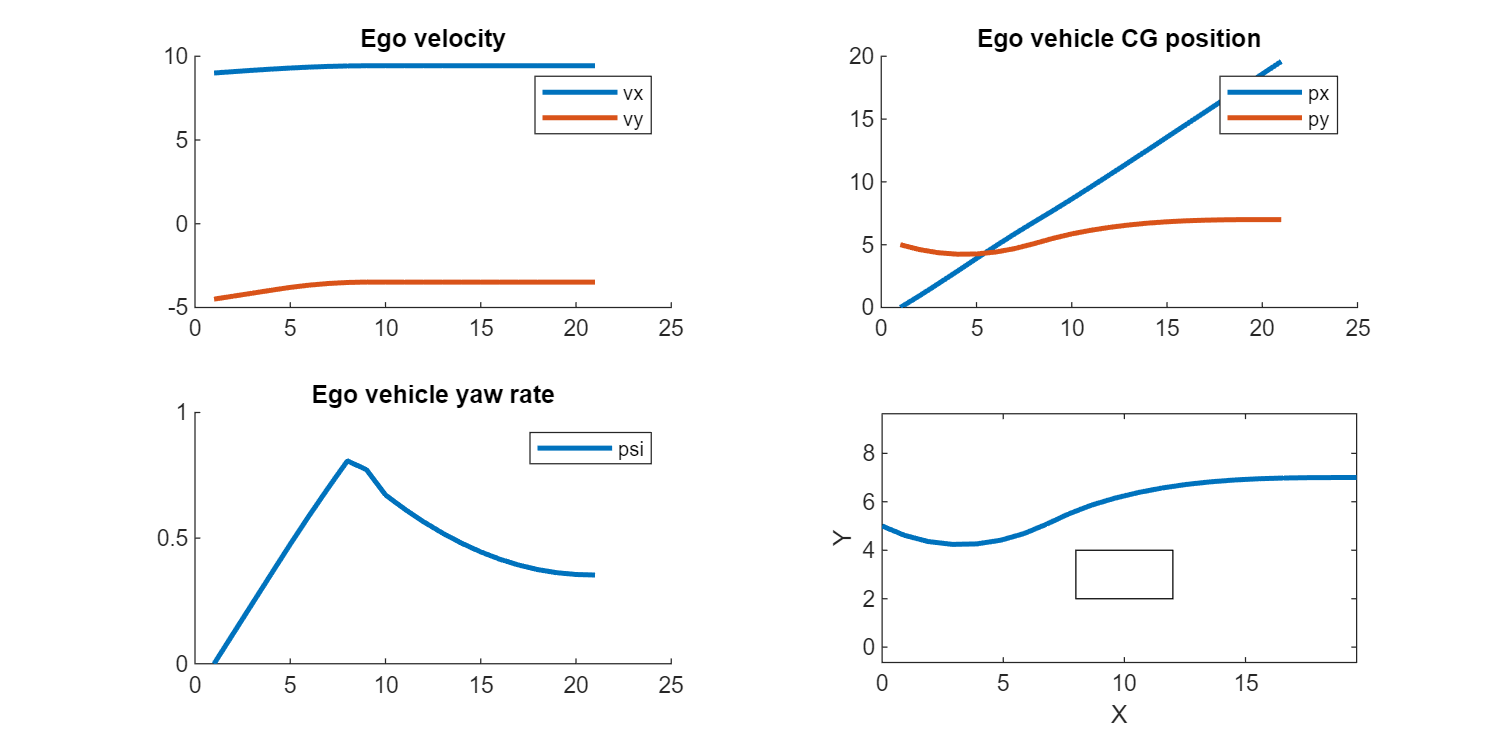

figure('Position',[100 100 800 400]);
tiledlayout(2,2)
nexttile;
hold on
plot(sol.value(OCP.vx),'LineWidth',2);
plot(sol.value(OCP.vy),'LineWidth',2);
legend('vx','vy');
title('Ego velocity')
nexttile;
hold on
plot(sol.value(OCP.px),'LineWidth',2);
plot(sol.value(OCP.py),'LineWidth',2);
legend('px','py')
title('Ego vehicle CG position');
nexttile;
hold on
plot(sol.value(OCP.psi),'LineWidth',2);
legend('psi')
title('Ego vehicle yaw rate')
nexttile;
plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
xlabel('X'); ylabel('Y')
rectangle('Position',[OCP.x_a 2 4 2]);
axis equal

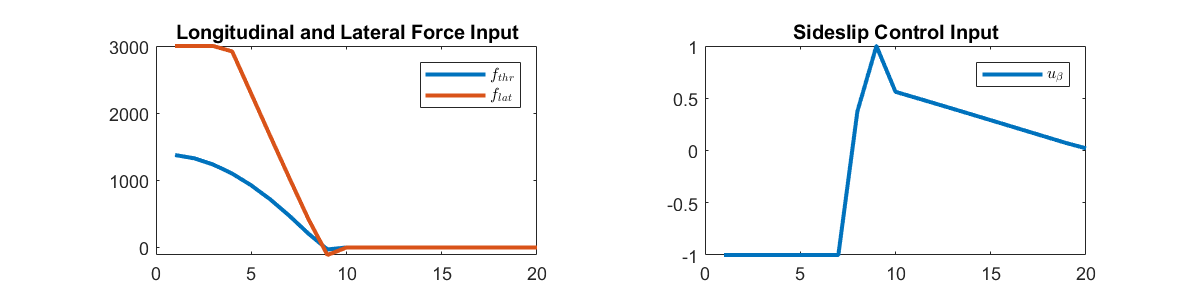


figure('Position',[100 100 800 200])
tiledlayout(1,2);
nexttile
plot(sol.value(OCP.f_thr),'LineWidth',2);
hold on;
plot(sol.value(OCP.f_lat),'LineWidth',2);
title('Longitudinal and Lateral Force Input');
legend('$f_{thr}$','$f_{lat}$','interpreter','latex')
nexttile;
plot(sol.value(OCP.u_beta),'LineWidth',2);
legend('$u_{\beta}$','interpreter','latex');
title('Sideslip Control Input');

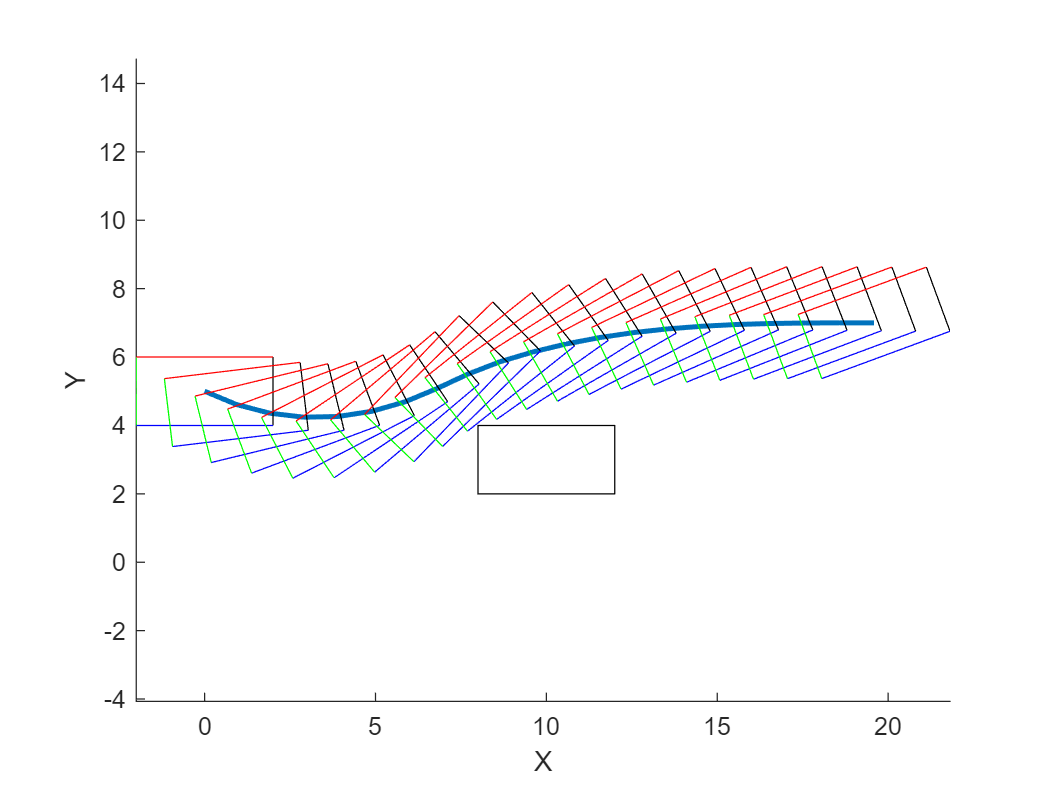

% overlap the vehicle body frame by frame onto the results
figure();
hold on;
plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
X_c_arr = sol.value(OCP.px);
Y_c_arr = sol.value(OCP.py);
psi_arr = sol.value(OCP.psi);

for i = 1:length(sol.value(OCP.px))
    drawVehicleBox(X_c_arr(i),Y_c_arr(i),psi_arr(i),4,2);
end
rectangle('Position',[OCP.x_a 2 4 2]);
xlabel('X'); ylabel('Y')
axis equal